# Module 1: Load and initialize

# Get Initial conditions for Descender

clear all

## Load model

lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_2"

plotnam = "2-Schlogl model"

plotnam = "2-Schlogl model"

model_name = "Selkov"

model_name = "Selkov"

plotnam = "Selkov model"

plotnam = "Selkov model"

model_name = "SYN3_FINAL"

model_name = "SYN3_FINAL"

plotnam = "12-D Syntrophy model"

plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"

model_name = "Cluster_3_catalyst"

plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"

model_name = "Cluster_3_catalyst_w_temp"

plotnam = "3-D Cluster model with catalysis & templating"

plotnam = "3-D Cluster model with catalysis & templating"

#### load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr

$$pos\_root\_arr = \left(\begin{array}{cc} 1 & 1\\ 2 & 2\\ 2.1654 & 1.0930\\ 1.0930 & 2.1654\\ 2.8367 & 1.1633\\ 1.1633 & 2.8367\\ 3 & 3\\ 2.9070 & 1.8346\\ 1.8346 & 2.9070 \end{array}\right)$$

hc_net

hc_net =      3     5     1
     4     6     1
     8     7     5
     9     7     6


i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

#### Linearize around fixed points and find eigensystem

V_mat = zeros(size(stab_idx,1),2*num_spec,2*num_spec);
D_mat = zeros(size(stab_idx,1),2*num_spec);
comp_ind = [];
for i = 1:size(stab_idx,1)        
    fp = pos_root_arr(stab_idx(i),:);
    p_z = zeros(1,num_spec);
    %Linearization matrix
    lin_mat = [ Ham_qp_mix'  Ham_p_hessian ;
               -Ham_q_hessian -Ham_qp_mix  ];
    val = subs(lin_mat,PS_coord,[fp p_z]);
    [V,D] = eig(val)
    V_mat(i,:,:) = V;
    D_mat(i,:) = diag(D)';
    if isreal(D) == 0
        comp_ind = [comp_ind i];
    end
end

$$V = \left(\begin{array}{cccc} 0.6951 & 0.6975 & 0.7071 & 0.7071\\ -0.6951 & 0.6975 & 0.7071 & -0.7071\\ 0.1300 & 0.1162 & 0 & 0\\ -0.1300 & 0.1162 & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{cccc} 2.3000 & 0 & 0 & 0\\ 0 & 2.0000 & 0 & 0\\ 0 & 0 & -2.0000 & 0\\ 0 & 0 & 0 & -2.3000 \end{array}\right)$$

$$V = \left(\begin{array}{cccc} 0.9765 & 0.9516 & 0.7071 & 0.7071\\ -0.2128 & 0.3059 & 0.7071 & -0.7071\\ 0.0239 & 0.0202 & 0 & 0\\ -0.0239 & 0.0202 & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{cccc} 1.4000 & 0 & 0 & 0\\ 0 & 1.1000 & 0 & 0\\ 0 & 0 & -1.1000 & 0\\ 0 & 0 & 0 & -1.4000 \end{array}\right)$$

$$V = \left(\begin{array}{cccc} -0.2128 & 0.3059 & 0.7071 & 0.7071\\ 0.9765 & 0.9516 & 0.7071 & -0.7071\\ -0.0239 & 0.0202 & 0 & 0\\ 0.0239 & 0.0202 & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{cccc} 1.4000 & 0 & 0 & 0\\ 0 & 1.1000 & 0 & 0\\ 0 & 0 & -1.1000 & 0\\ 0 & 0 & 0 & -1.4000 \end{array}\right)$$

$$V = \left(\begin{array}{cccc} 0.7066 & 0.7067 & 0.7071 & 0.7071\\ -0.7066 & 0.7067 & 0.7071 & -0.7071\\ 0.0267 & 0.0236 & 0 & 0\\ -0.0267 & 0.0236 & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{cccc} 2.3000 & 0 & 0 & 0\\ 0 & 2.0000 & 0 & 0\\ 0 & 0 & -2.0000 & 0\\ 0 & 0 & 0 & -2.3000 \end{array}\right)$$

comp_ind


comp_ind =

     []



If comp_ind is non-empty i.e. no complex valued eigenenvalues of lin_mat, imply only straight line initial conditions are needed. For more detail, refer paper. 

### Straight line Initial Conditions

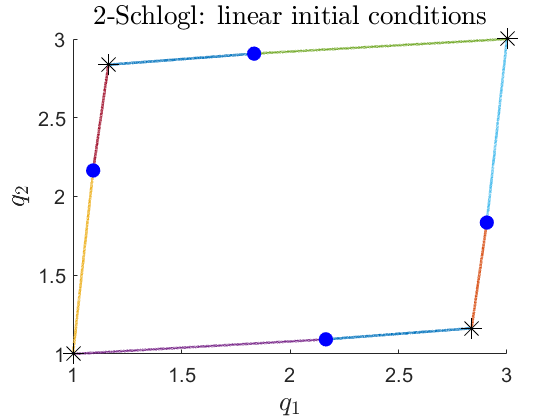

traj_pt = 2000;
figure()
hold on       

for sad_pt = 1:size(hc_net,1)
    for stab_pt_choice = 1:2
        p_o_int = pos_root_arr(hc_net(sad_pt,stab_pt_choice+1),:);
        p_o_int = [p_o_int; pos_root_arr(hc_net(sad_pt,1),:)];
        t_fin = 1;
        t_i = 0 : t_fin/(traj_pt-1) : t_fin;
        traj_ic = t_i'*(p_o_int(2,:))+(1-t_i')*(p_o_int(1,:));
        
        plot(traj_ic(:,1),traj_ic(:,2:end),'Linewidth',2)
        plot(traj_ic(1,1),traj_ic(1,2:end),'k*','MarkerSize',15)
        plot(traj_ic(end,1),traj_ic(end,2:end),'bo','MarkerSize',10,'MarkerFaceColor','b')
        
        save('..\Data\' + model_name + '_initcond_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'straight.mat', 'p_o_int','traj_ic')
    end
end
hold off
ax=gca;
ax.FontSize = 15;
xlabel('$q_1$','interpreter','latex','FontSize',20)
ylabel('$q_2$','interpreter','latex','FontSize',20)
title(plotnam + ': linear initial conditions','interpreter','latex','FontSize',20)

saveas(gcf,'Plots/'+model_name+'_linear_IC.png')

### Spiral Initial Conditions

#### Linearize around fixed points and find eigensystem

V_mat = zeros(size(stab_idx,1),2*num_spec,2*num_spec);
D_mat = zeros(size(stab_idx,1),2*num_spec);
comp_ind = [];
for i = 1:size(stab_idx,1)        
    fp = pos_root_arr(stab_idx(i),:);
    p_z = zeros(1,num_spec);
    %Linearization matrix
    lin_mat = [ Ham_qp_mix'  Ham_p_hessian ;
               -Ham_q_hessian -Ham_qp_mix  ];
    val = subs(lin_mat,PS_coord,[fp p_z]);
    [V,D] = eig(val)
    V_mat(i,:,:) = V;
    D_mat(i,:) = diag(D)';
    if isreal(D) == 0
        comp_ind = [comp_ind i];
    end
end

$$V = \left(\begin{array}{cccc} 0.9051 & 0.9051 & 0.9936 & 0.9936\\ -0.0168+0.4128\,\mathrm{i} & -0.0168-0.4128\,\mathrm{i} & -0.0290+0.1094\,\mathrm{i} & -0.0290-0.1094\,\mathrm{i}\\ 0.0110+0.0027\,\mathrm{i} & 0.0110-0.0027\,\mathrm{i} & 0 & 0\\ 0.0019+0.0998\,\mathrm{i} & 0.0019-0.0998\,\mathrm{i} & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{cccc} 0.6553-0.0769\,\mathrm{i} & 0 & 0 & 0\\ 0 & 0.6553+0.0769\,\mathrm{i} & 0 & 0\\ 0 & 0 & -0.6553-0.0769\,\mathrm{i} & 0\\ 0 & 0 & 0 & -0.6553+0.0769\,\mathrm{i} \end{array}\right)$$

$$V = \left(\begin{array}{cccc} 0.7124 & 0.7124 & 0.8367 & 0.8367\\ -0.5285-0.4616\,\mathrm{i} & -0.5285+0.4616\,\mathrm{i} & -0.4349+0.3329\,\mathrm{i} & -0.4349-0.3329\,\mathrm{i}\\ 0.0027-0.0056\,\mathrm{i} & 0.0027+0.0056\,\mathrm{i} & 0 & 0\\ -0.0020-0.0093\,\mathrm{i} & -0.0020+0.0093\,\mathrm{i} & 0 & 0 \end{array}\right)$$

$$D = \left(\begin{array}{cccc} 0.5102+0.6821\,\mathrm{i} & 0 & 0 & 0\\ 0 & 0.5102-0.6821\,\mathrm{i} & 0 & 0\\ 0 & 0 & -0.5102-0.6821\,\mathrm{i} & 0\\ 0 & 0 & 0 & -0.5102+0.6821\,\mathrm{i} \end{array}\right)$$

comp_ind

comp_ind =      1     2


x_ic_arr = zeros(size(stab_idx,1),2*num_spec);
eig_arr = [];
for i = 1:size(stab_idx,1)
    eigval = D_mat(i,:);
    [a,b] = max(real(eigval));   %Most repelling direction
    x_ic_arr(i,:) = V_mat(i,:,b);
    eig_arr = [eig_arr D_mat(i,b)];
end
x_ic_arr

x_ic_arr =    0.9051 + 0.0000i  -0.0168 + 0.4128i   0.0110 + 0.0027i   0.0019 + 0.0998i
   0.7124 + 0.0000i  -0.5285 - 0.4616i   0.0027 - 0.0056i  -0.0020 - 0.0093i


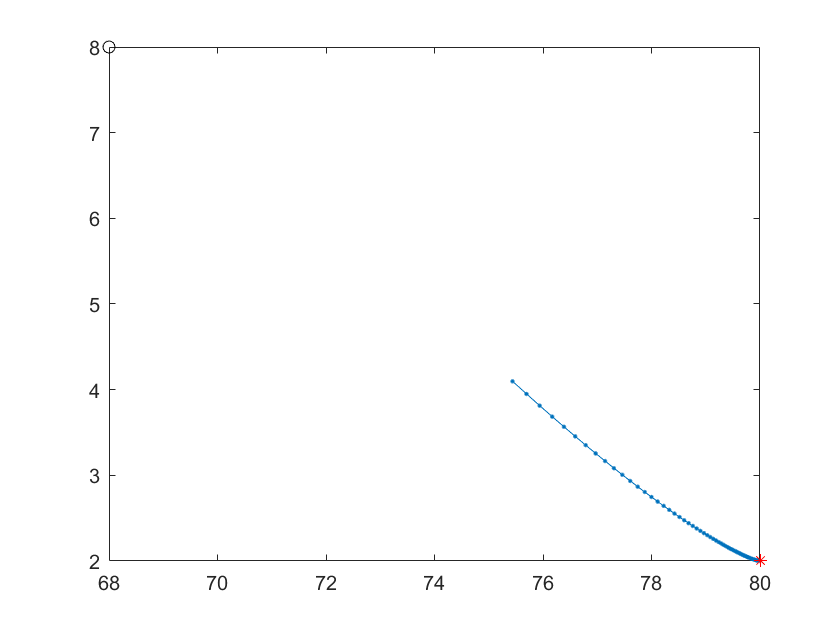

i = 1; j = 2; 
x_targ = pos_root_arr(hc_net(i,1),:);
x_in = pos_root_arr(hc_net(i,j+1),:);
st_idx = find(stab_idx==hc_net(i,j+1));
dt  = 10^(-1); t_min = 0; t_max = 10; t_ran = t_min:dt:t_max; t_ran = t_ran';
%try different combinations of negative sign in a_const and conj in k_lamb 
a_const = -1/norm(x_ic_arr(st_idx,:))*0.01; 
k_lamb = eig_arr(st_idx);
%a_const = 1/norm(x_ic_arr(st_idx,:))*0.04; 
%k_lamb = conj(eig_arr(st_idx));
v_traj = real(a_const*exp(t_ran.*(k_lamb)).*x_ic_arr(st_idx,:));
v_traj = v_traj(:,1:num_spec) + x_in;
figure()
plot(v_traj(:,1),v_traj(:,2),'.-')
hold on
plot(x_in(1),x_in(2),'r*')
plot(x_targ(1),x_targ(2),'ko')
hold off

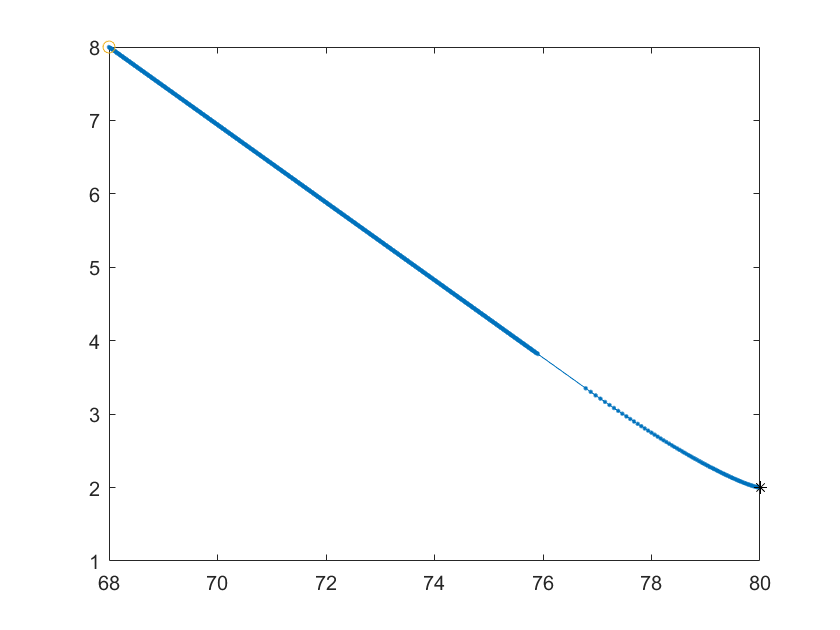

syms tau
format long
v_traj = real(a_const*exp(tau*k_lamb).*x_ic_arr(st_idx,1:num_spec));
v_traj = v_traj + x_in;

dydx = diff(v_traj(2),tau)/diff(v_traj(1),tau);
dydx_line = (v_traj(2)-x_targ(2))/(v_traj(1)-x_targ(1));
time_end = vpasolve(dydx_line==dydx,tau,8.8);
dt = 5*10^(-2);
t_max = double(time_end); t_min = -4; t_ran = t_min:dt:t_max; t_ran = t_ran';
%t_ran = logspace(-6,log10(t_max),200)';
v_traj = real(a_const*exp(t_ran.*(k_lamb)).*x_ic_arr(st_idx,:));
v_traj = v_traj(:,1:num_spec) + x_in;
v_traj = [x_in ; v_traj];
%Get tangent line by linear interpolation
traj_pts = 3000 - size(t_ran,1);
t_fin = 1;
t_i = t_fin/(traj_pts-1)+0.1 : t_fin/(traj_pts-1) : t_fin;
st_line = t_i'*(x_targ)+(1-t_i')*(v_traj(end,:));
traj_ic = [v_traj;st_line];
figure()
plot(traj_ic(:,1),traj_ic(:,2),'.-')
hold on
plot(x_in(1),x_in(2),'k*')
plot(x_targ(1),x_targ(2),'o')
hold off

size(traj_ic)

ans =         2727           2


traj_ic = double(traj_ic);


save('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat', 'traj_ic')

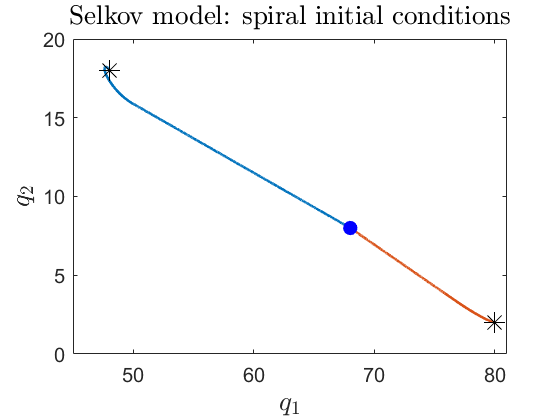

i = 1; j = 1;
load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat', 'traj_ic')
traj_ic_1 = traj_ic;
i = 1; j = 2;
load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat', 'traj_ic')
traj_ic_2 = traj_ic;
figure()
plot(traj_ic_1(:,1),traj_ic_1(:,2),'Linewidth',2)
hold on
plot(traj_ic_2(:,1),traj_ic_2(:,2),'Linewidth',2)
plot(traj_ic_1(1,1),traj_ic_1(1,2:end),'k*','MarkerSize',15)
plot(traj_ic_1(end,1),traj_ic_1(end,2:end),'bo','MarkerSize',10,'MarkerFaceColor','b')
plot(traj_ic_2(1,1),traj_ic_2(1,2:end),'k*','MarkerSize',15)
hold off
xlim([45 81])

ax=gca;
ax.FontSize = 15;
xlabel('$q_1$','interpreter','latex','FontSize',20)
ylabel('$q_2$','interpreter','latex','FontSize',20)
title(plotnam + ': spiral initial conditions','interpreter','latex','FontSize',20)
saveas(gcf,'Plots/'+model_name+'_spiral_IC.png')